## PID controller design

- Define PID gain as Kp, KI and KD variable.

- Assign Kp, KI and KD.

- Run code below

clc; clear; warning off;
Kp = 1900;
KI = 0;
KD = 2.5;

simout = sim('Lab_PositionControl.slx');

Found algebraic loop containing: 
Lab_PositionControl/Gain4
Lab_PositionControl/Lead//Lag Compensator
Lab_PositionControl/Gain
Lab_PositionControl/Gain3
Lab_PositionControl/Gain2
Lab_PositionControl/Add
Lab_PositionControl/Manual Switch (discontinuity)
Lab_PositionControl/Saturation (discontin

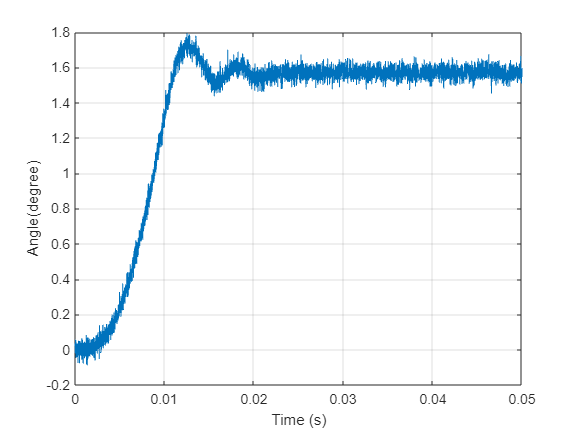


y = simout.Angle;
t = simout.tout;
plot(t,y); grid on;
xlabel('Time (s)'); ylabel('Angle(degree)');

stepinfo(y,t)

ans = struct with fields:
         RiseTime: 0.0062
    TransientTime: 0.0500
     SettlingTime: 0.0500
      SettlingMin: 1.3276
      SettlingMax: 1.7936
        Overshoot: 12.4426
       Undershoot: 5.4887
             Peak: 1.7936
         PeakTime: 0.0125


ess = abs((pi/2) - mean(y(10000:end)))

ess = 0.0028

## ZN method

- Find time delay from open loop system

clc; clear;
simout = sim('Lab_Identification.slx');

w = simout.w;
v = simout.v;
t = simout.tout;

plot(t,w);

Using output figure to find time delay. 

2. Using time delay to find PID gain for each case

`Controller   `$K_P$        $K_{I\;\;\;}$      $K_{D\;}$

P                       $\frac{1}{\textrm{RL}}$

PI                      $\frac{0\ldotp 9}{\textrm{RL}}$      $\frac{L}{0\ldotp 3}$

PID                   $\frac{1\ldotp 2}{\textrm{RL}}$       $2L$      $0\ldotp 5L$

When $L=T_{d\;}$ and $R=\frac{K}{\tau \;}$

clc; clear;
Td = 1.4e-3; K = 1.435; tau = 0.081;

L = Td; R = K/tau;

Kp = 1/(R*L); KI = 0; KD = 0;
simout1 = sim("Lab_VelocityControl.slx");

Found algebraic loop containing: 
Lab_VelocityControl/Gain3
Lab_VelocityControl/Transfer Fcn
Lab_VelocityControl/Derivative
Lab_VelocityControl/Gain2
Lab_VelocityControl/Gain
Lab_VelocityControl/Add
Lab_VelocityControl/Manual Switch (discontinuity)
Lab_VelocityControl/Saturation (discontinuity)
<a

w1 = simout1.w;
v1 = simout1.v;
t1 = simout1.tout;

Kp = 0.9/(R*L); KI = L/0.3; KD = 0;
simout2 = sim("Lab_VelocityControl.slx");

Found algebraic loop containing: 
Lab_VelocityControl/Gain3
Lab_VelocityControl/Transfer Fcn
Lab_VelocityControl/Derivative
Lab_VelocityControl/Gain2
Lab_VelocityControl/Gain
Lab_VelocityControl/Add
Lab_VelocityControl/Manual Switch (discontinuity)
Lab_VelocityControl/Saturation (discontinuity)
<a

w2 = simout2.w;
v2 = simout2.v;
t2 = simout2.tout;

Kp = 1.2/(R*L); KI = 2*L; KD = 0.5*L;
simout3 = sim("Lab_VelocityControl.slx");

Found algebraic loop containing: 
Lab_VelocityControl/Gain3
Lab_VelocityControl/Transfer Fcn
Lab_VelocityControl/Derivative
Lab_VelocityControl/Gain2
Lab_VelocityControl/Gain
Lab_VelocityControl/Add
Lab_VelocityControl/Manual Switch (discontinuity)
Lab_VelocityControl/Saturation (discontinuity)
<a

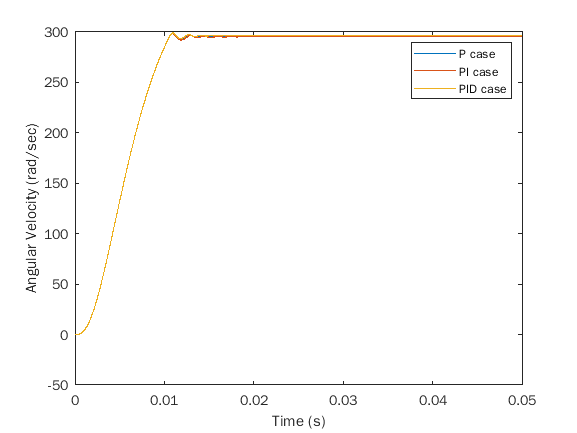

w3 = simout3.w;
v3 = simout3.v;
t3 = simout3.tout;

figure(1)
plot(t1,w1,t2,w2,t3,w3)
xlabel('Time (s)'); ylabel('Angular Velocity (rad/sec)');
legend('P case','PI case','PID case')
saveas(gcf,'Velocity.png')

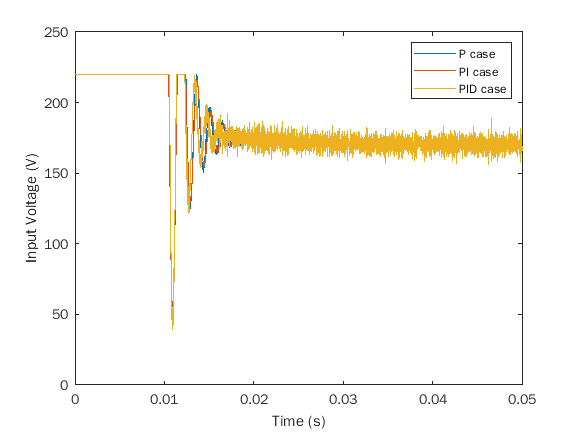


figure(2)
plot(t1,v1,t2,v2,t3,v3)
xlabel('Time (s)'); ylabel('Input Voltage (V)');
legend('P case','PI case','PID case')
saveas(gcf,'InputVoltage.png')

Root Locus Design

s = tf('s');
G  = 1.5/(s*(0.007*s+1));

Td = 400;
C = 1+s/Td;

rlocus(C*G)
dcm = datacursormode;
dcm.Enable = 'on';
dcm.DisplayStyle = 'window';
